clf;
syms a1 q1
x = trchain2('R(q1),Tx(a1)',q1)

$$x = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & a_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & a_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 \end{array}\right)$$

double(subs(x,[a1,q1],[0.1,0.2]))

ans =     0.9801   -0.1987    0.0980
    0.1987    0.9801    0.0199
         0         0    1.0000


trot2(0.2)*transl2(0,0.1)

ans =     0.9801   -0.1987   -0.0199
    0.1987    0.9801    0.0980
         0         0    1.0000


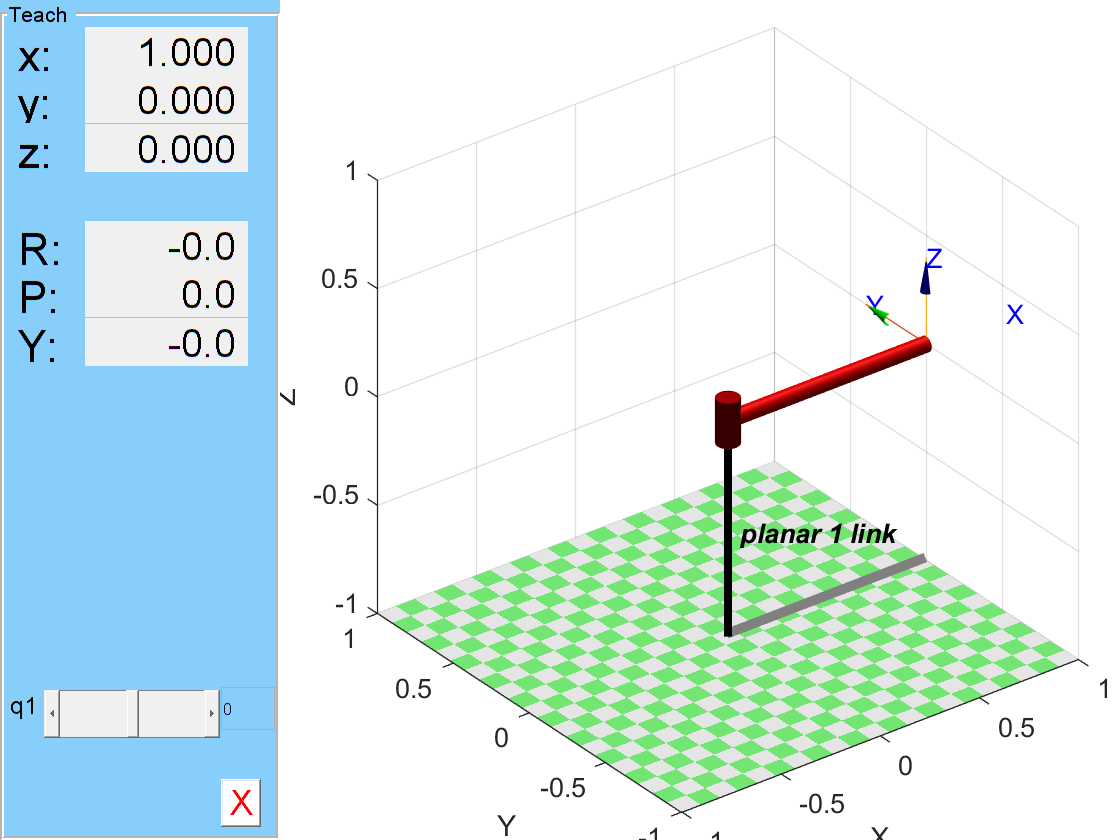

clf;
mdl_planar1
p1.teach

syms a1 a2 q1 q2
x2 = trchain2('R(q1),Tx(a1),R(q2),Tx(a2)',[q1,q2])

double(subs(x2,[a1 a2 q1 q2],[1,1,0.2,0.3]))

clf;
mdl_planar2
p2.teach
p2.plot([0,pi/2])

hold on
p2.plot([pi/2,-pi/2])

syms a1 a2 a3 q1 q2 q3
x3 = trchain2('R(q1),Tx(a1),R(q2),Tx(a2),R(q3),Tx(a3)',[q1,q2,q3])
double(subs(x3,[a1 a2 a3 q1 q2 q3],[1,1,2,0.2,0.3,0.5]))